*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 1 : Simulate a Simplest 5G Network**

#    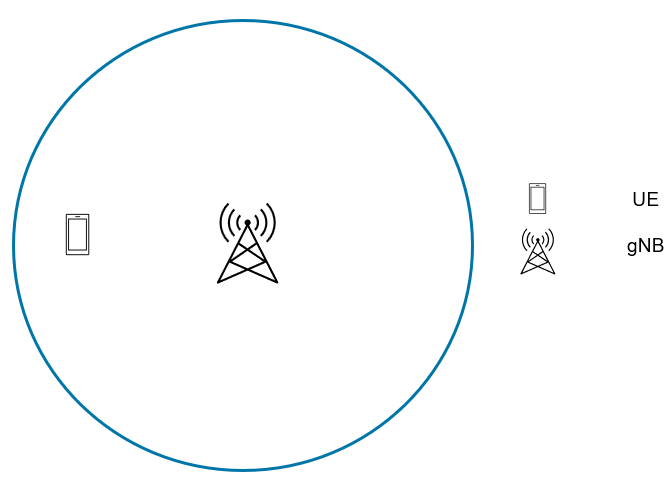

This exercise demonstrates a **basic 5G NR network simulation** using one gNB (base station) and 1 UE (user equipment). The goals are to:

- Understand how to create and configure gNB and UE nodes

- Set up the 5G network

- Simluate the network and capture statistics and explore visualization tools 

The following figure shows all the layers of NR node that can be modeled in MATLAB  

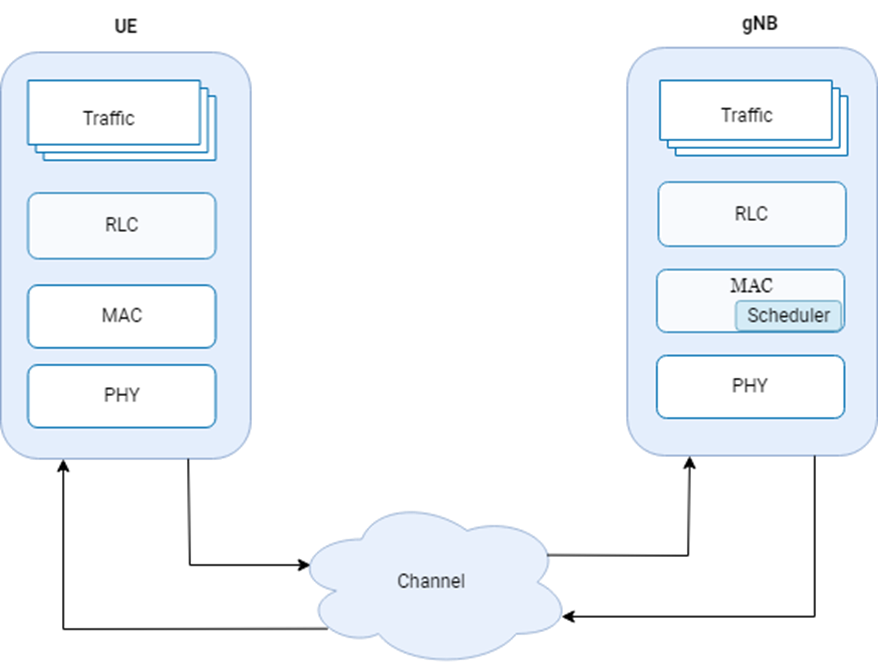

#### Close any previously opened figures and add the path to the helpers and utilities directories 

- Reset the random number generator for reproducibility

rng("default") 
addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
cleanUp();

#### Initialize global variables and Wireless Network Simulator

- Initialize the Wireless Network Simulator.

- Set the NR cell radius in meters. 

- A typical micro cell range is 500 meters to 2 kilometers, commonly used in urban areas.

- Specify the number of frames to simulate.

- Set the UE position in Cartesian coordinates, for example [0 0 30] meters.

networkSimulator = wirelessNetworkSimulator.init;
cellRadius = 500; 
numFrameSimulation = 30; 
simulationTime = numFrameSimulation*0.01; 
gNBPosition = [0 0 30]; 

# Task #1/3 Create a NR base station 

% Use nrGNB() function to create a NR base station 
% Store NR base station in a variable named "gNB"
% Hint:Click the following link, and see the "Syntax" section.

[Help on creating 5G base station ](https://www.mathworks.com/help/5g/ref/nrgnb.html)

% Note : use the following values to start with
%    Position=gNBPosition
%    SubcarrierSpacing=15000
%    CarrierFrequency=2.6e9
%    ChannelBandwidth=5e6
%    DuplexMode="FDD"
%    PHYAbstractionMethod="none"

% Write your code here
gNB = nrGNB( Name="gNB",...
    Position=gNBPosition, ...
    SubcarrierSpacing=15000, ...
    CarrierFrequency=2.6e9, ...
    ChannelBandwidth=5e6, ...
    DuplexMode="FDD", ...
    PHYAbstractionMethod="none");


#### Configure Scheduler at NR base station (gNB)

Downlink Channel State Information (CSI) Measurement Signal

Specifies the type of CSI measurement signal used, either "SRS" or "CSI-RS".

Scheduling Algorithms

- "RoundRobin" — Allocates equal scheduling opportunities to all UE nodes.

- "BestCQI" — Prioritizes the UE node with the highest Channel Quality Indicator (CQI).

- "ProportionalFair" — Balances fairness and throughput, combining aspects of both RoundRobin and BestCQI scheduling.

configureScheduler(gNB,CSIMeasurementSignalDL="CSI-RS",Scheduler="RoundRobin");

# Task #2/3 Create a NR user equipment  

% Use nrUE() function to create a NR base station 
% Store NR base station in a variable named "UE"
% Hint:Click the following link, and see the "Syntax" section.

[Help on creating 5G user equipment ](https://www.mathworks.com/help/releases/R2025a/5g/ref/nrue.html)

% Create a UE (User Equipment) node
% Note : use the following values to start with
%    Name=ueName
%    Position=uePosition
%    ReceiveGain=0
%    NumTransmitAntennas=1
%    NumReceiveAntennas=1
%    PHYAbstractionMethod="none"

% Write your code here
ueName ="UE-1";       % UE Name 
uePosition = [200 100 1]; % UE position
UE = nrUE(Name=ueName, ...
    Position=uePosition, ...
    ReceiveGain=0, ...
    NumTransmitAntennas=1, ...
    NumReceiveAntennas=1, ...
    PHYAbstractionMethod="none")

UE =   nrUE with properties:

                    Name: "UE-1"
                Position: [200 100 1]

   Read-only properties:
             NoiseFigure: 6
             ReceiveGain: 0
           TransmitPower: 23
     NumTransmitAntennas: 1
      NumReceiveAntennas: 1
    PHYAbstractionMethod: "none"
         ConnectionState: "Idle"
                      ID: 2


# Task #3/3 Create the Network   

% Use connectUE() function to connect gNB to corresponding UEs
% Hint:Click the following link, and see the "Syntax" section.
% Note : use the following values to start with
% gNB 
% UE    

[Help on connecting UEs to gNB  ](https://www.mathworks.com/help/5g/ref/nrgnb.connectue.html)

% <enter code below>
connectUE(gNB, UE);

#### **Add nodes to the network simulator **

addNodes(networkSimulator, gNB);
addNodes(networkSimulator, UE);

#### **Install an application layer on gNB and UE, enable bidirectional traffic **

appDataRate =  10e3; % Application data rate in kilobits per second (kbps)
installAppLayer(networkSimulator, appDataRate)

#### Add channel Model 

channelModel = "3GPP TR 38.901";
addChannel(networkSimulator,channelModel);

#### Enable visualization, logging and IQ data capture

- Visualize the network that you have created 

- Sample rate indicates the visualization refresh rate in Hertz

- Show the cell boundary of each gNB

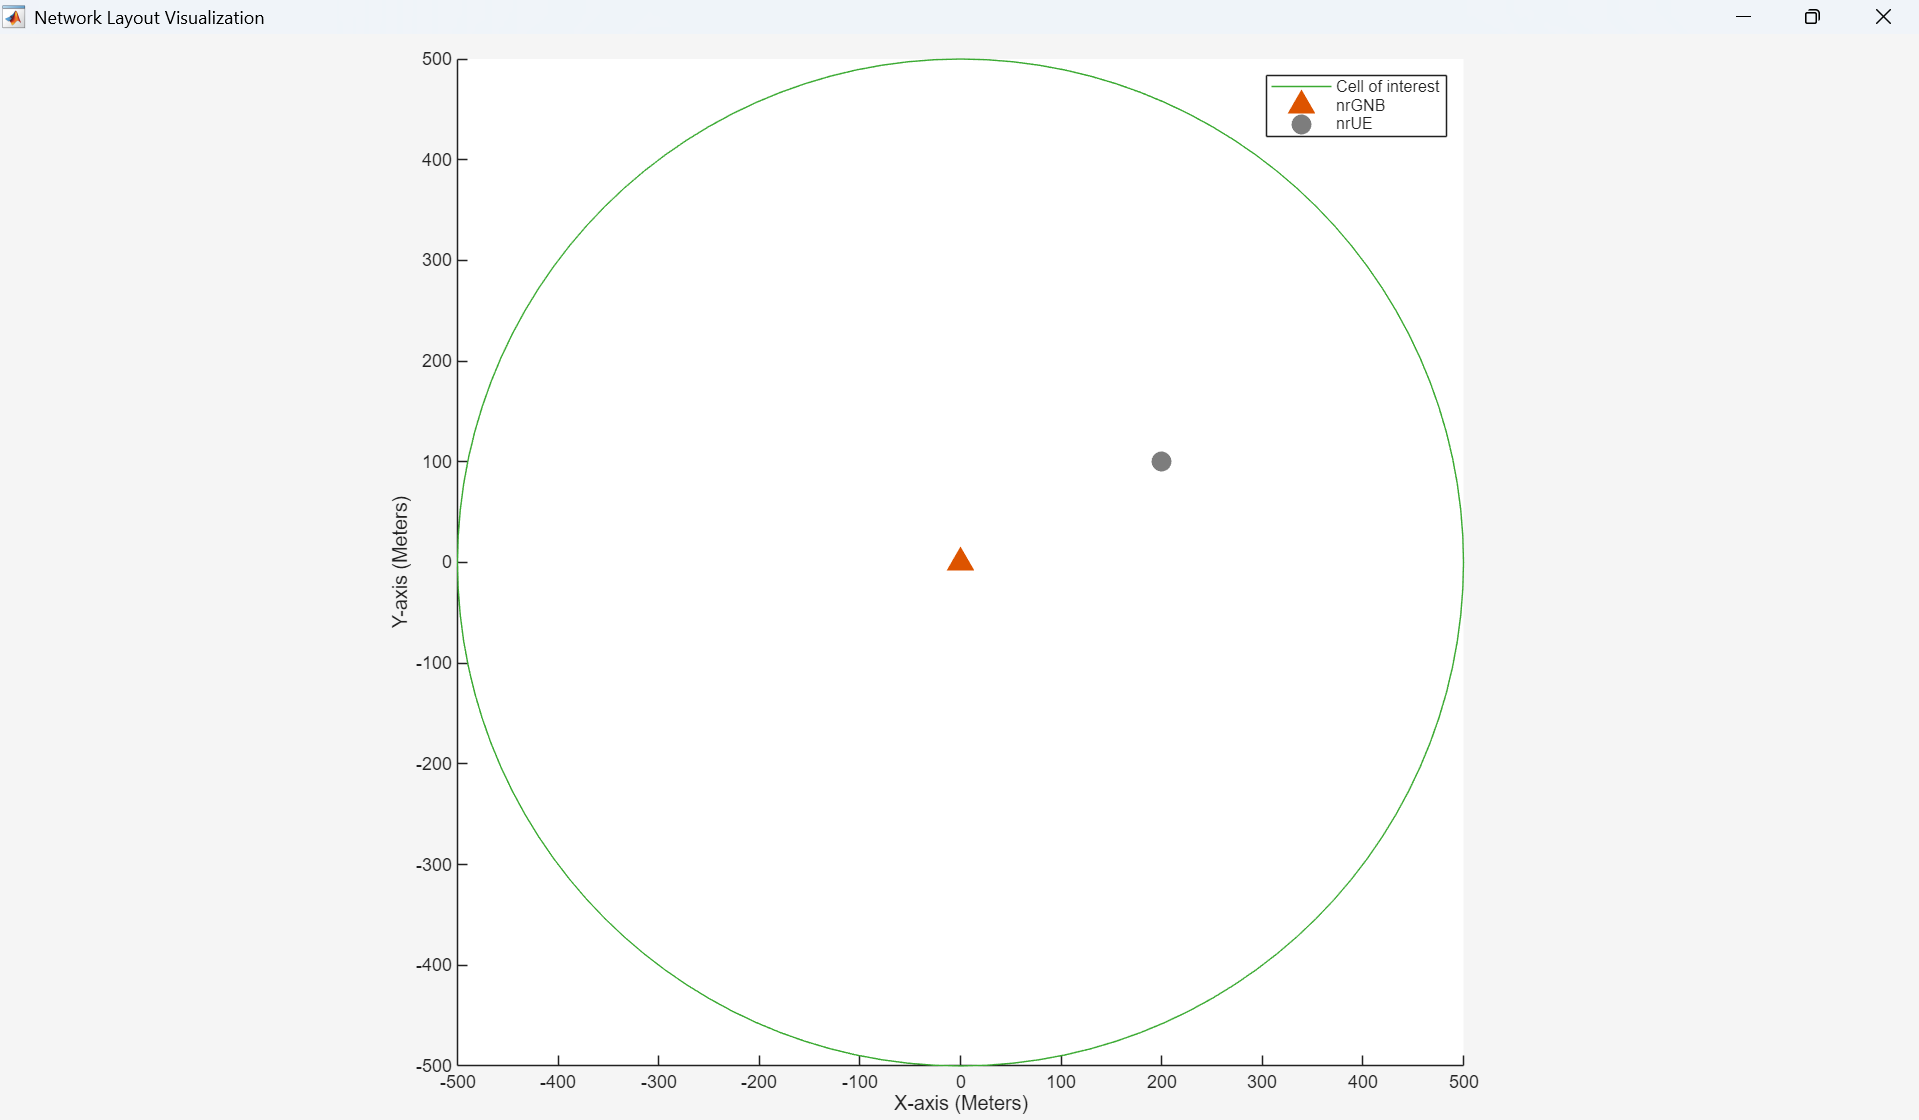

networkVisualizer = helperNetworkVisualizer(SampleRate=100); 
showBoundaries(networkVisualizer,gNBPosition,cellRadius,gNB.ID);

**Visualize PHY and MAC Performance**   

- Block Error Rate (BLER) – Ratio of erroneous blocks to total transmitted blocks.

- Transmission Rate (Tx Rate) – Data rate at which packets are transmitted.

- Throughput – Effective data rate successfully received.

- Resource Share Percentage – Portion of total radio resources allocated to each user.

- Buffer Status – Amount of data pending transmission in the buffer.

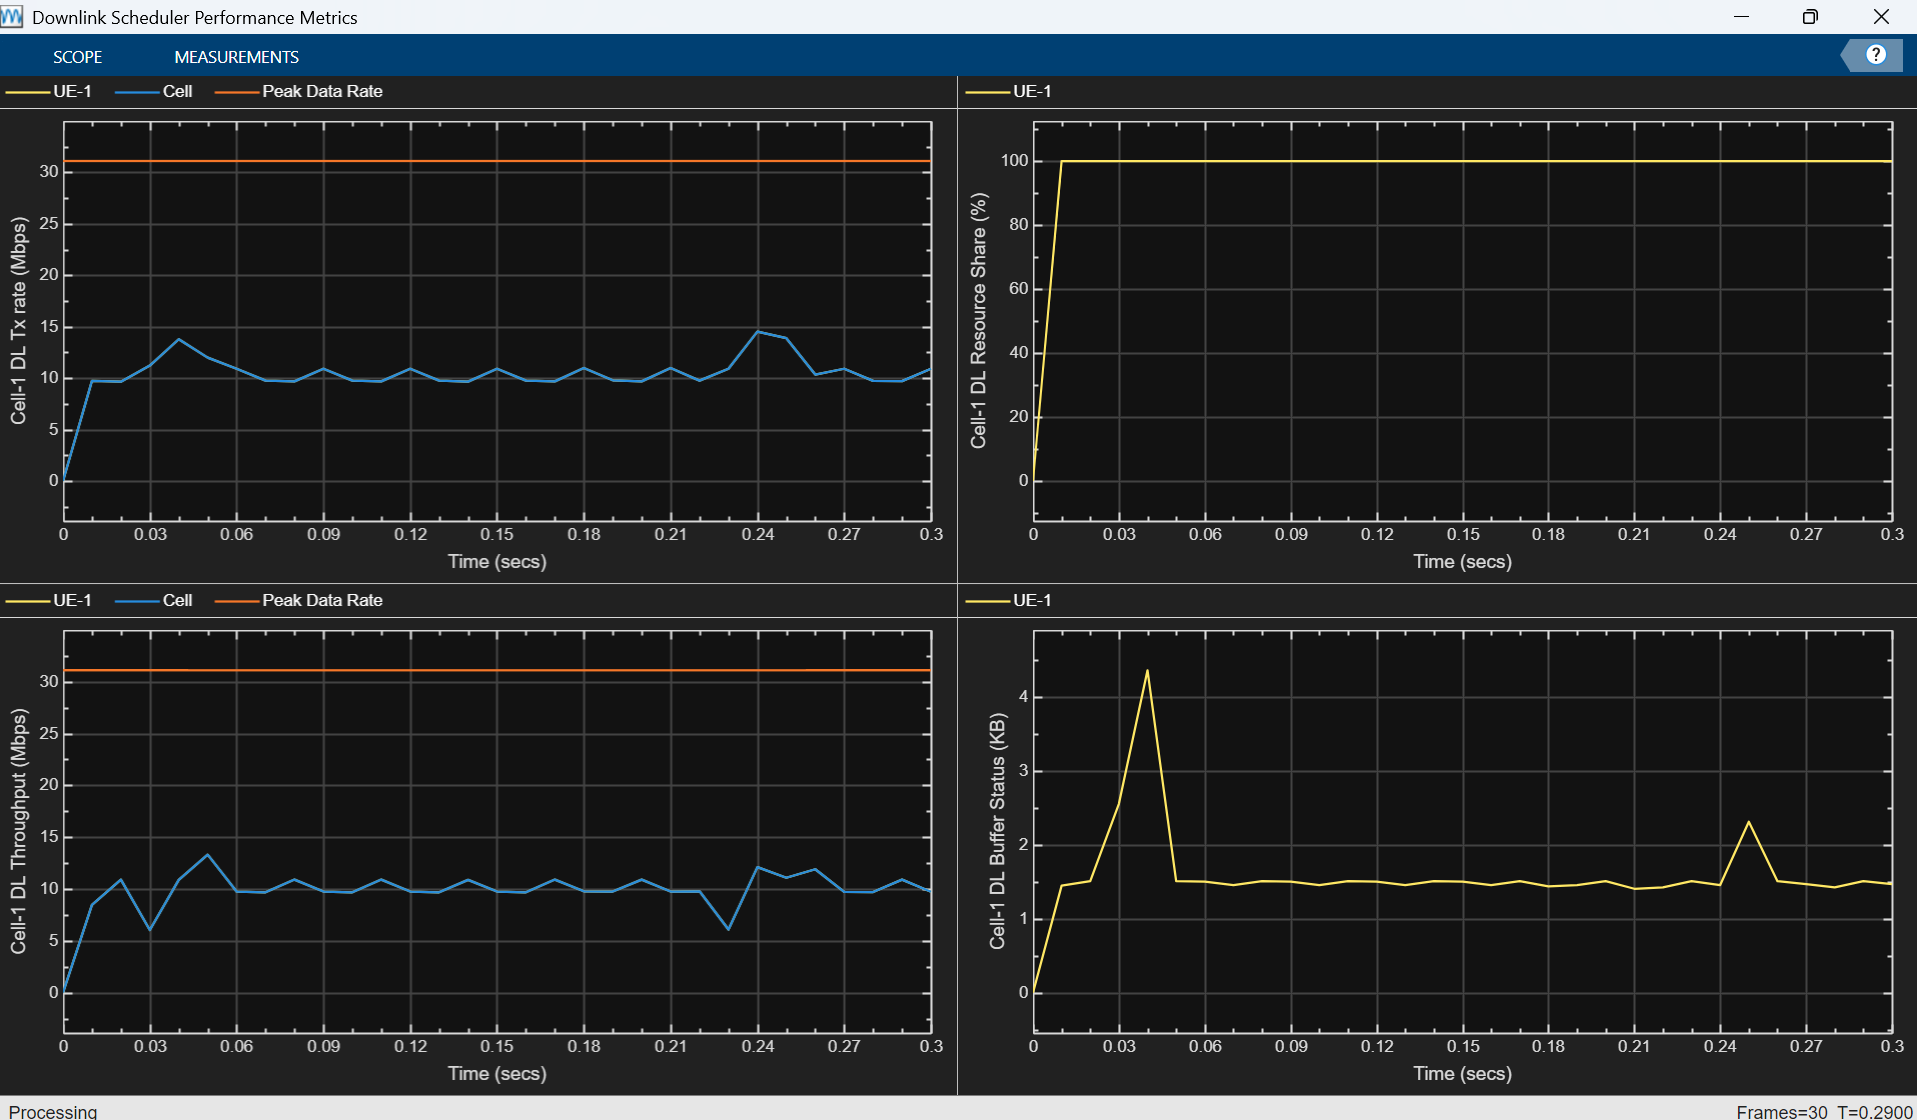

Direction  = false;
metricsVisualizer = helperNRMetricsVisualizer(gNB,UE,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=true,LinkDirection=Direction);

**Set up the Logger**

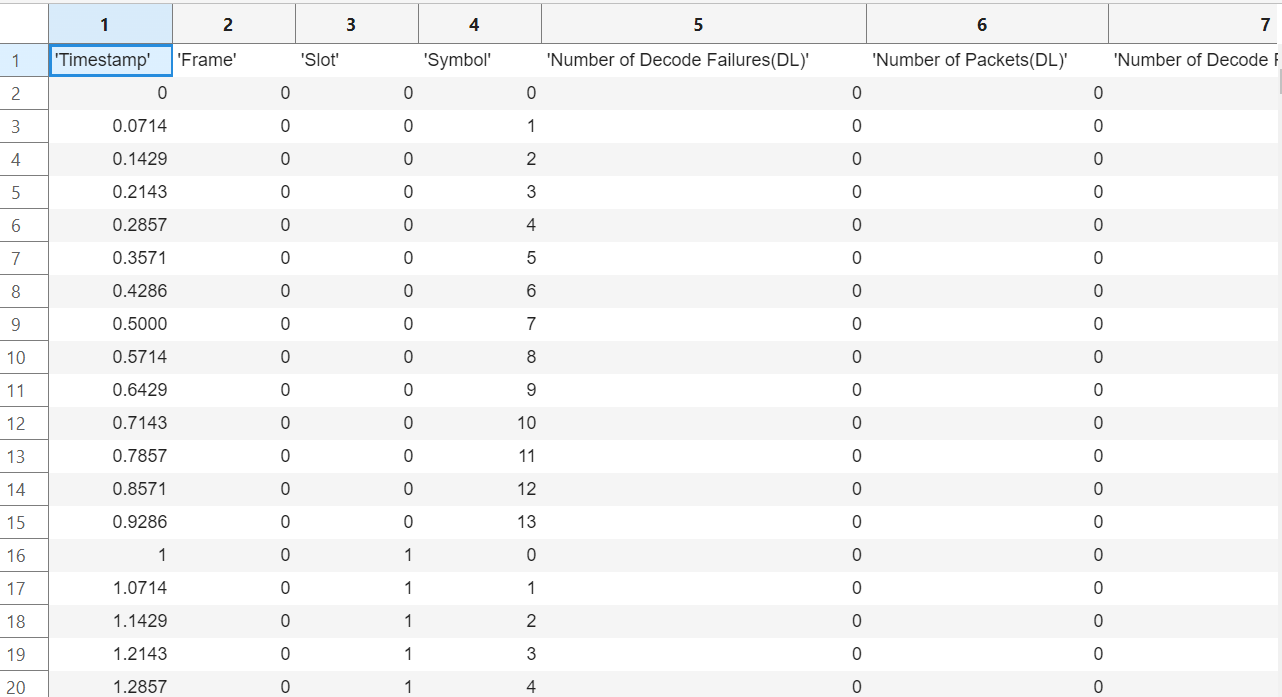

enableTraces = true;
if enableTraces
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UE);
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UE);
    simulationLogFile = "simulationLogs"; % For logging the simulation traces
end

**Capture IQ Samples**

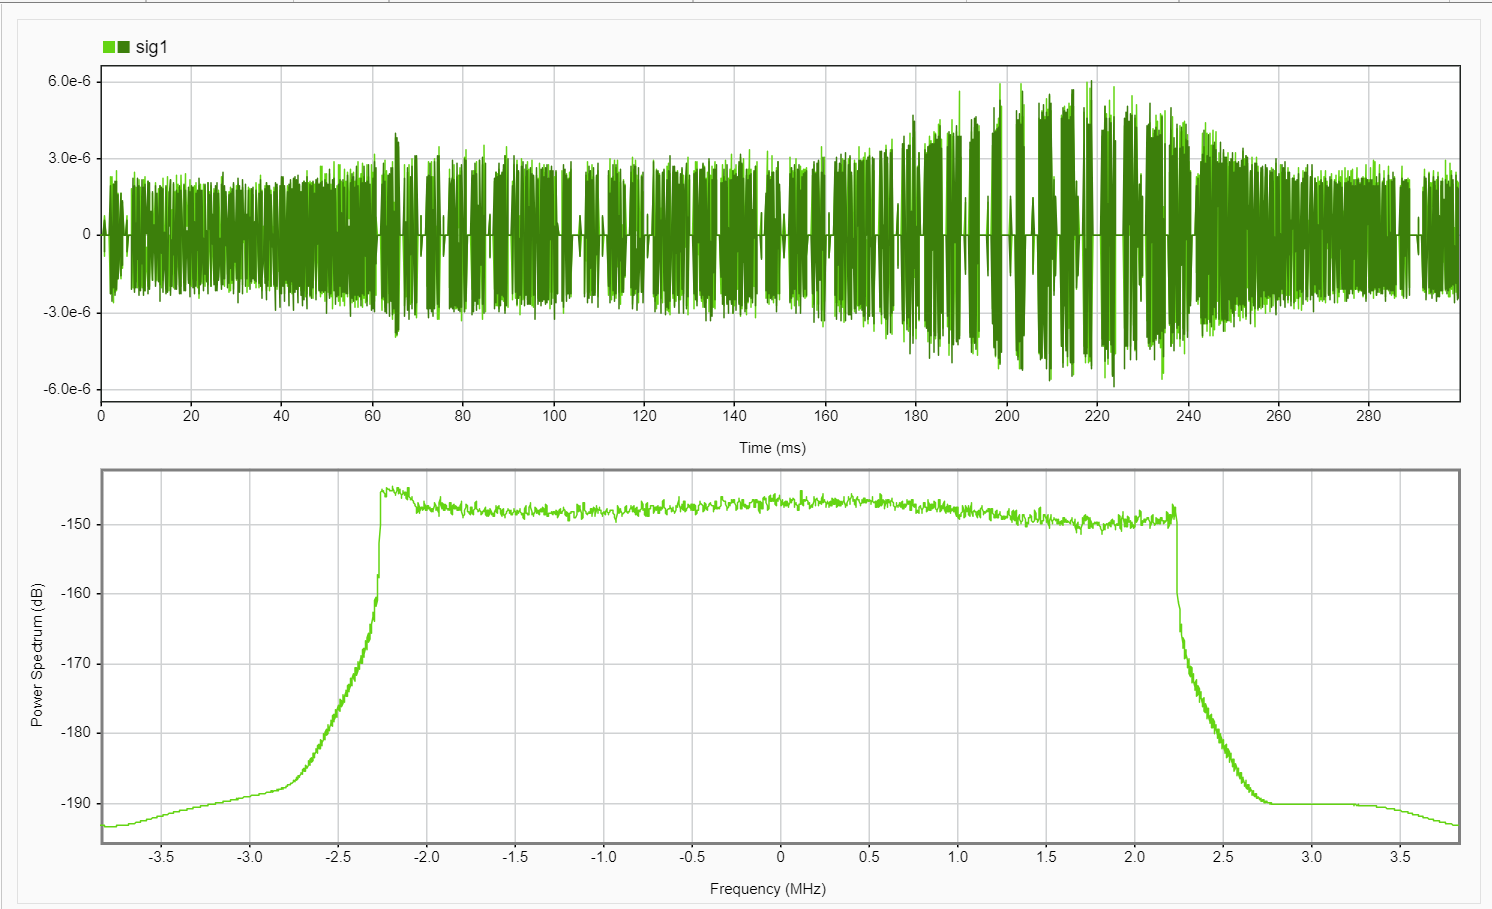

enableIQCapture = true;
if enableIQCapture
    iqSampleObj = helperCaptureIQSamples(gNB,Bandwidth=gNB.ChannelBandwidth);
end

#### Run the Simulation 

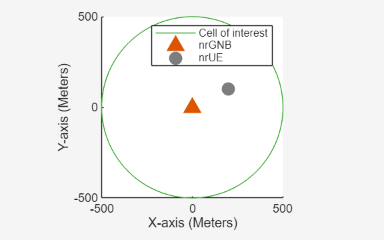

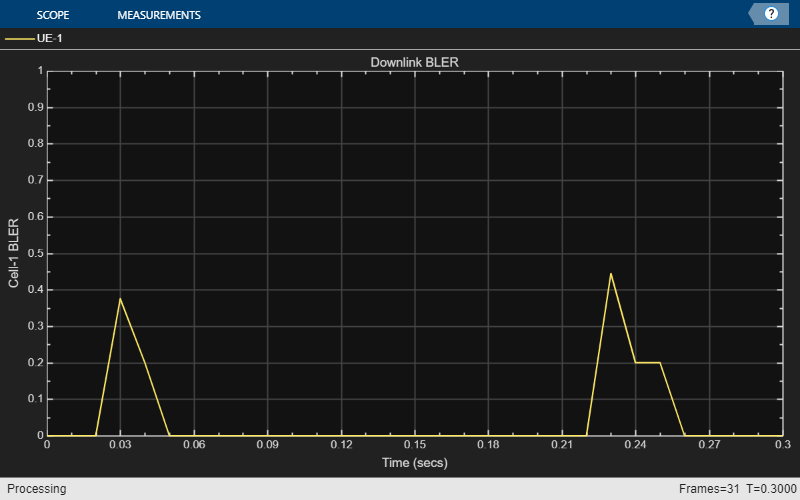

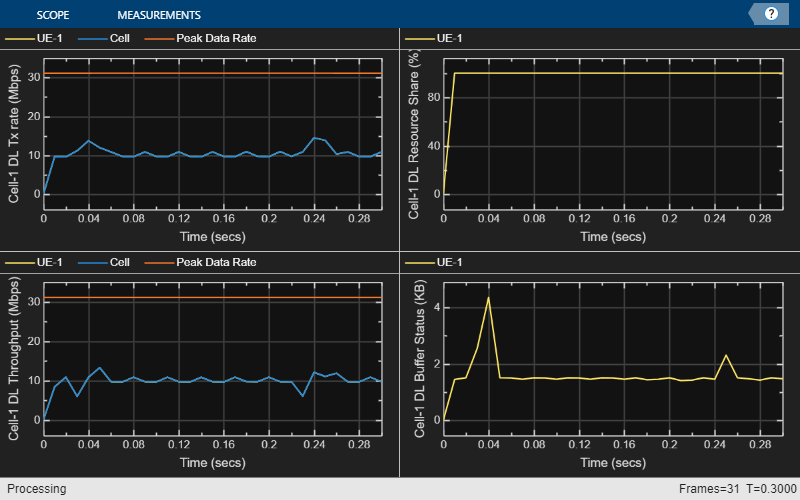

run(networkSimulator, simulationTime);

**Save Logs for all Layers **

if enableTraces
   saveTraces(networkSimulator,simSchedulingLogger,simPhyLogger,simulationLogFile);
end

#### Get statistics from the gNB

gnbStats = statistics(gNB, "all");

#### gNB statistics 

gnbStats.App

ans = struct with fields:
    TransmittedPackets: 251
      TransmittedBytes: 376500
       ReceivedPackets: 245
         ReceivedBytes: 367500
          Destinations: [1×1 struct]


gnbStats.RLC

ans = struct with fields:
      TransmittedPackets: 451
        TransmittedBytes: 376289
    RetransmittedPackets: 0
      RetransmittedBytes: 0
         ReceivedPackets: 446
           ReceivedBytes: 370052
          DroppedPackets: 0
            DroppedBytes: 0
            Destinations: [1×1 struct]


gnbStats.MAC

ans = struct with fields:
     TransmittedPackets: 246
       TransmittedBytes: 379412
        ReceivedPackets: 202
          ReceivedBytes: 371360
        Retransmissions: 13
    RetransmissionBytes: 20493
           Destinations: [1×1 struct]


gnbStats.PHY

ans = struct with fields:
    TransmittedPackets: 259
       ReceivedPackets: 239
        DecodeFailures: 37
          Destinations: [1×1 struct]


**Get statistics from UEs**

ueStats = statistics(UE);

#### UE statistics 

ueStats.PHY

ans = struct with fields:
    TransmittedPackets: 240
       ReceivedPackets: 258
        DecodeFailures: 13


ueStats.MAC

ans = struct with fields:
     TransmittedPackets: 203
       TransmittedBytes: 373057
        ReceivedPackets: 245
          ReceivedBytes: 377939
        Retransmissions: 37
    RetransmissionBytes: 73800
       DLTransmissionRB: 4269
     DLRetransmissionRB: 227
       ULTransmissionRB: 4578
     ULRetransmissionRB: 904


ueStats.RLC

ans = struct with fields:
      TransmittedPackets: 448
        TransmittedBytes: 371743
    RetransmittedPackets: 0
      RetransmittedBytes: 0
         ReceivedPackets: 449
           ReceivedBytes: 374822
          DroppedPackets: 0
            DroppedBytes: 0


ueStats.App

ans = struct with fields:
    TransmittedPackets: 251
      TransmittedBytes: 376500
       ReceivedPackets: 249
         ReceivedBytes: 373500


At the end of the simulation, compare the achieved values for system performance indicators with theoretical peak values (considering zero overheads). Performance indicators displayed are:

- Achieved data rate (UL and DL)

- Achieved spectral efficiency (UL and DL)

- Block error rate (BLER) observed for UEs (UL and DL) 

The calculated peak values are in accordance with 3GPP TR 37.910.

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 31.11 Mbps. Achieved cell DL throughput: 10.08 Mbps
Achieved DL throughput for each UE: [10.08]
Peak DL spectral efficiency: 6.22 bits/s/Hz. Achieved DL spectral efficiency for cell: 2.02 bits/s/Hz
Block error rate for each UE in the DL direction: [0.05]



#### IQ sample visualization

enableIQVisualization  = true;
if enableIQVisualization && enableIQCapture
    signalAnalyzer(iqSampleObj.IQSamples.Data,SampleRate=7.68e6);
end

*Copyright 2025 The MathWorks, Inc.*